# Original Cube

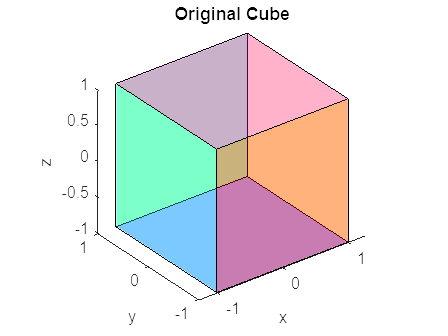

figure()

verticesCube = [
    -1, 1, 1,-1,-1, 1, 1 ,-1;
    -1,-1, 1, 1,-1,-1, 1, 1;
    -1,-1,-1,-1, 1, 1, 1, 1;
     1, 1, 1, 1, 1, 1, 1, 1
    ];

facesCube = [
    1, 2, 6, 5;
    2, 3, 7, 6;
    3, 4, 8, 7;
    4, 1, 5, 8;
    1, 2, 3, 4;
    5, 6, 7, 8
    ];

DrawShape(verticesCube, facesCube, 'flat')
title("Original Cube");
xlabel('x','FontSize',10)
ylabel('y','FontSize',10)
zlabel('z','FontSize',10)
axis equal;
view(3)
hold on

## Задание 2. Измените масштаб кубика

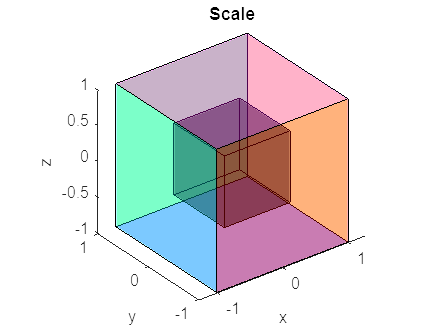

figure('Name','Scale', NumberTitle='off')

verticesCube2 = getTranslated_Scale(0,0,0,0.5, 0.5, 0.5)*verticesCube;
DrawShape(verticesCube, facesCube,'flat');
DrawShape(verticesCube2, facesCube, 'black');

title("Scale");
xlabel('x','FontSize',10)
ylabel('y','FontSize',10)
zlabel('z','FontSize',10)
axis equal;
view(3)

hold on

## Задание 3. Переместите кубик

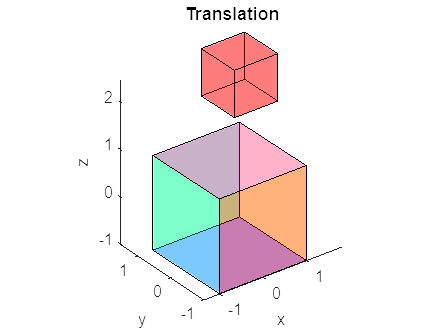

figure('Name','Translation', NumberTitle='off')

verticesCube3 = getTranslated_Scale(1, 1, 2, 0.5, 0.5, 0.5)*verticesCube;

DrawShape(verticesCube, facesCube, 'flat')
DrawShape(verticesCube3, facesCube, 'red')

title("Translation")
xlabel('x','FontSize',10)
ylabel('y','FontSize',10)
zlabel('z','FontSize',10)
axis equal;
view(3)

hold on

## Задание 4. Вращение кубика

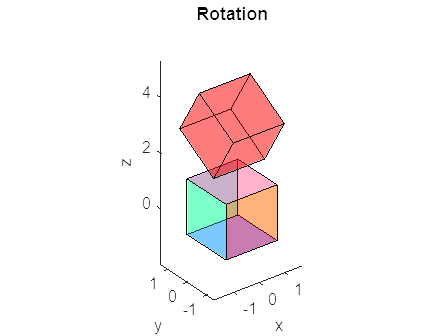

figure('Name','Rotation', NumberTitle='off')

verticesCube4 = getTranslated_Scale(0,0,3,1,1,1)* getRotated_x(30)*verticesCube;

DrawShape(verticesCube, facesCube, 'flat');
DrawShape(verticesCube4, facesCube, 'red');

title("Rotation")
xlabel('x','FontSize',10)
ylabel('y','FontSize',10)
zlabel('z','FontSize',10)
axis equal;
view(3)

hold on

## **Задание 5. Вращение кубика около одной вершины.**

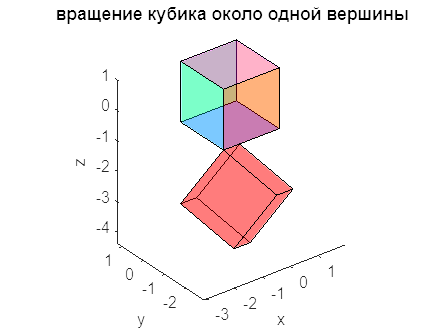

figure('Name','вращение кубика около одной вершины', NumberTitle='off')

% Выбираем вершину, вокруг которой будет вращаться куб
rotation_point = verticesCube(:,1);

% Делаем вершину центром
center = verticesCube - repmat(rotation_point, 1, size(verticesCube, 2));

% Поскольку последняя строка не меняет своего значения, мы просто берем 
% первые три строки и умножаем их на матрицу вращательного преобразования.
rotatio_X = [1      0       0;
             0  cos(45)  sin(45);
             0 -sin(45)  cos(45)];

rotation_Y = [cosd(160)  0   sind(160);
                  0      1      0     ;
             -sind(160)  0   cosd(160)];

rotation_Z= [cosd(50)   -sind(50)     0;
             sind(50)    cosd(50)     0;
                   0           0      1];

rotatedVertices = rotatio_X*rotation_Y*rotation_Z*center(1:3,:);

%Возвращаем куб в исходную центральную точку
finalVertices = rotatedVertices + rotation_point(1:3,:);

%добавляем в матрицу последнюю строку со значениями 1
verticesCube5 = [finalVertices; ones(1, size(rotatedVertices, 2))];

DrawShape(verticesCube, facesCube, 'flat');
DrawShape(verticesCube5, facesCube, 'red');

title("вращение кубика около одной вершины")
xlabel('x','FontSize',10)
ylabel('y','FontSize',10)
zlabel('z','FontSize',10)
axis equal;
view(3)

hold on

## **Задание 6. Реализация камеры**

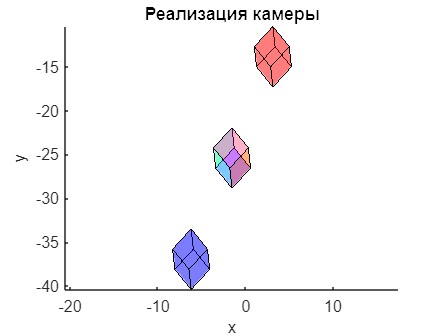

figure()
verticesCube_1 = getTranslated_Scale(5,0,5, 1, 1, 1) *verticesCube;
verticesCube_2 = getTranslated_Scale(-5,0, -5, 1, 1, 1)*verticesCube;

% параметры для камеры
cameraPos = [5 2 15];
cameraTarget =[6 5 1];
cameraUp = [0 1 0];

viewMatrix1 = lookat(cameraPos, cameraTarget, cameraUp) * verticesCube;
viewMatrix2 = lookat(cameraPos, cameraTarget, cameraUp) * verticesCube_1;
viewMatrix3 = lookat(cameraPos, cameraTarget, cameraUp) * verticesCube_2;

DrawShape(viewMatrix1, facesCube, 'flat')
DrawShape(viewMatrix2, facesCube, 'red')
DrawShape(viewMatrix3, facesCube, 'blue')

title("Реализация камеры");
xlabel('x','FontSize',10)
ylabel('y','FontSize',10)
zlabel('z','FontSize',10)

axis equal
view([0 90])
hold on

## Задание 7. Реализация перспективы.

 Матрица проекции будет отвечать за:

- Соотношение сторон (Aspect Ratio): отрегулируйте значения x и y на основе значений ширины и высоты экрана:  $a=\frac{h}{\;w}$

$\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack \to \left\lbrack \begin{array}{c}
\textrm{ax}\\
y\\
z
\end{array}\right\rbrack$, преобразование в место экрана

- Поле зрения (Field of view) : отрегулируйте значения x и y в зависимости от угла поля зрения: $S=\frac{1}{\;\tan \left(\frac{\theta }{2}\right)}$


$$\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack \to \left\lbrack \begin{array}{c}
\textrm{afx}\\
\textrm{fy}\\
z
\end{array}\right\rbrack ,\textrm{преобразование}\;в\;\textrm{место}\;\textrm{экрана}$$


- Нормализация (Normalization): настройте значения x, y и z в диапазоне от -1 до 1:   

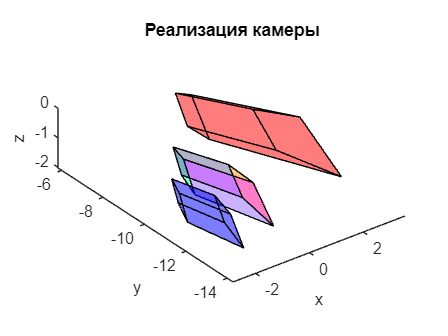

figure()
fov = 5;
aspect = 1;
n = 3;
f = 2;

Perspective_1 = createPerspective(fov,aspect,n,f,viewMatrix1);
Perspective_2 = createPerspective(fov,aspect,n,f,viewMatrix2);
Perspective_3 = createPerspective(fov,aspect,n,f,viewMatrix3);

DrawShape(Perspective_1, facesCube, 'flat')
DrawShape(Perspective_2, facesCube, 'red')
DrawShape(Perspective_3, facesCube, 'blue')
title("Реализация камеры");
xlabel('x','FontSize',10)
ylabel('y','FontSize',10)
zlabel('z','FontSize',10)

xlim([0 20])
ylim([0 20])
zlim([0 20])


view(3)
axis equal;
hold on


% figure()
% projection_Matrix = perspective(fov, aspect, n, f);
% projection_Matrix_final_1 = M_mul_v_project(projection_Matrix,viewMatrix1);
% projection_Matrix_final_2 = M_mul_v_project(projection_Matrix,viewMatrix2);
% projection_Matrix_final_3 = M_mul_v_project(projection_Matrix,viewMatrix3);
% 
% DrawShape(projection_Matrix_final_1, facesCube, 'flat')
% DrawShape(projection_Matrix_final_2, facesCube, 'red')
% DrawShape(projection_Matrix_final_3, facesCube, 'blue')



## Transformation Matrix

function matrix = getTranslated_Scale(dx, dy, dz, Sx, Sy, Sz)
matrix = [Sx 0 0 dx;
          0 Sy 0 dy;
          0 0 Sz dz;
          0 0 0 1
         ];
end

% Rotation
function matrix = getRotated_x(theta)
matrix = [1        0         0       0;
          0 cosd(theta) -sind(theta) 0;
          0 sind(theta)  cosd(theta) 0;
          0        0         0       1
         ];

end
function matrix = getRotated_y(theta)
matrix = [ cosd(theta)  0   sind(theta)  0;
                0       1       0        0;
          -sind(theta)  0   cosd(theta)  0;
              0         0       0        1
         ];
end

function matrix = getRolated_z(theta)
matrix = [cosd(theta) -sind(theta) 0 0;
          sind(theta)  cosd(theta) 0 0;
               0           0       1 0;
               0           0       0 1
         ];
end

% вращаться вокруг любой оси
function matrix = getRotate(Rx, Ry, Rz, theta)
matrix = [ cosd(theta)+Rx^2*(1-cosd(theta))       Rx*Ry*(1-cosd(theta))-Rz*sind(theta)    Rx*Rz*(1-cosd(theta))+Ry*sind(theta)   0;
           Ry*Rx*(1-cosd(theta))+Rz*sind(theta)   cosd(theta)+Ry^2*(1-cosd(theta))        Ry*Rz*(1-cosd(theta))-Rx*sind(theta)   0;
           Rz*Rx*(1-cosd(theta))-Ry*sind(theta)   Rz*Ry*(1-cosd(theta))-Rx*sind(theta)    cosd(theta)+Rz^2*(1-cosd(theta))       0;
                        0                                      0                                       0                         1
          ];
end

## Functions

% Function for permisson 6
function viewMatrix = lookat(eye, target, up)
    f = normalize(eye - target); % axis z
    s = normalize(cross(up,f)); % axis x
    u = cross(f,s);             % axis y

viewMatrix =[ s(:,1)  s(:,2)   s(:,3)   -dot(s,eye);
              u(:,1)  u(:,2)   u(:,3)   -dot(u,eye);
              f(:,1)  f(:,2)   f(:,3)   -dot(f,eye);
                 0       0        0           1
             ];

end

% Permission 7
function Perspective = createPerspective(fovy, aspect, near, far,v)
      top = near * tand((fovy)/2);
      bottom = -top;
      right = top * aspect;
      left = -right;
    %Move the Frustum Apex to the Origin
    frustum_to_Origin = [
                         1         0         0         -(left+right)/2;
                         0         1         0         -(bottom+top)/2;
                         0         0         1          0
                         0         0         0          1
                         ];

    perspec_cal = [
                    near 0   0   0;
                    0   near 0   0;
                    0    0   1   0;
                    0    0  -1   0
                    ];

    %Scale the View Window to (-1,1) to (+1,+1)
    scale_wind = [
             2/(right-left)         0           0            0;
                    0       2/(top-bottom)      0            0;
                    0               0           1            0;
                    0               0           0            1
            ];
   %Mapping Depth (z values) to (-1,+1)

  c1 = 2*far*near/(near-far);
  c2 = (far+near)/(far-near);
  
  map = [1 0   0  0;
         0 1   0  0;
         0 0 -c2 c1;
         0 0 -1   0];

  Perspective = scale_wind*perspec_cal*map*frustum_to_Origin*v;
end


% Function for permission 7
function projM = perspective(fov, aspect, n, f)
    projM = eye(4);
    projM(1,1) = 1/aspect*(tand(fov/2));
    projM(2,2) = 1/tand(fov/2);
    projM(3,3) = (f+n)/(f-n);
    projM(4,3) = f*n/(f-n);
    projM(3,4) = 1;
    projM(4,4) = 0;
end

% perform perspective divide with original z-value that is now stored in w 
function matrix_multi_project = M_mul_v_project(projM, v)
    matrix_multi_project = projM*v;
    if matrix_multi_project(4) ~= 0.0
        matrix_multi_project(1)= matrix_multi_project(1)/matrix_multi_project(4);
        matrix_multi_project(2)= matrix_multi_project(2)/matrix_multi_project(4);
        matrix_multi_project(3)= matrix_multi_project(3)/matrix_multi_project(4);
    end
end

## **Draw Cube**

function DrawShape (vertices , faces , flat )
patch ('Vertices', ( vertices (1:3,:) ./ vertices (4 ,:))', 'Faces', faces ,'FaceVertexCData',hsv(6),'FaceColor', flat, 'facealpha', 0.3)
end